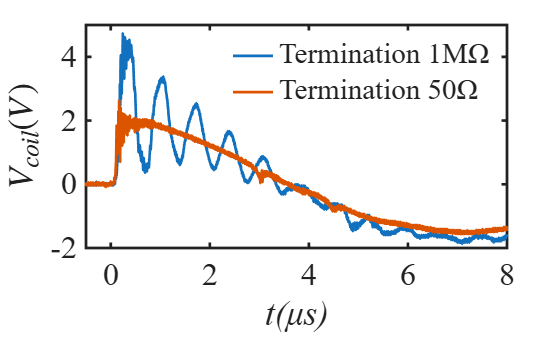

clear; clc;
load("Workspace.mat");

LineWidth = 2;

% =========================================================
% Time Alignment
% =========================================================
t1 = linspace(0, 5*30E-6, 150000);
t2 = linspace(0, 20*30E-6, 7500000);

t2 = t2 - 375000*2*80E-12;
t2 = t2 + 0.6E-6;

t2 = t2(7500000/20*2:end);
didt_matrix2 = didt_matrix2(7500000/20*2:end, 1);

t1 = (t1 - 15.5E-6)*1E6;
t2 = (t2 - 15.5E-6)*1E6;

% =========================================================
% Coil Voltage Comparison
% =========================================================
figure;

plot(t1, didt_matrix, t2, didt_matrix2, ...
    'LineWidth', LineWidth);

xlim([-0.5 8]);
ylim([-2 5]);

set(gca, 'FontName', 'Times New Roman', ...
    'FontSize', 24, ...
    'LineWidth', 2);

xlabel('t(\mus)', 'FontAngle', 'italic');
ylabel('$V_{coil} (V)$', 'Interpreter', 'latex');

h = legend(["Termination 1M\Omega", "Termination 50\Omega"]);
h.Color = 'none';
h.EdgeColor = 'none';
h.BackgroundAlpha = 0;

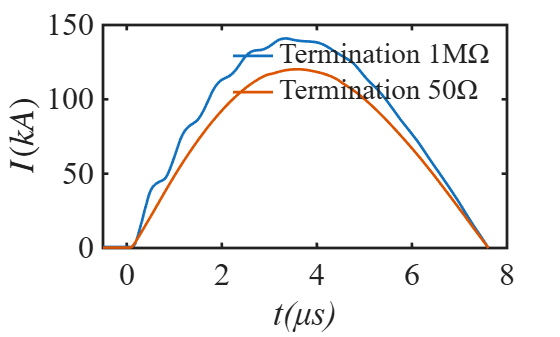


% =========================================================
% Cumulative Integration
% =========================================================
i_matrix1 = cumtrapz(t1, didt_matrix)*28.846;
i_matrix2 = cumtrapz(t2, didt_matrix2)*28.846;

% =========================================================
% Coil Current Comparison
% =========================================================
figure;

plot(t1, i_matrix1, t2, i_matrix2, ...
    'LineWidth', LineWidth);

xlim([-0.5 8]);
ylim([0 150]);

set(gca, 'FontName', 'Times New Roman', ...
    'FontSize', 24, ...
    'LineWidth', 2);

xlabel('t(\mus)', 'FontAngle', 'italic');
ylabel('$I(kA)$', 'Interpreter', 'latex');

h = legend(["Termination 1M\Omega", "Termination 50\Omega"]);
h.Color = 'none';
h.EdgeColor = 'none';
h.BackgroundAlpha = 0;